imu = imuSensor('accel-gyro-mag')

imu =   imuSensor with properties:

          IMUType: 'accel-gyro-mag'
       SampleRate: 100
      Temperature: 25
    MagneticField: [27.5550 -2.4169 -16.0849]
    Accelerometer: [1×1 accelparams]
        Gyroscope: [1×1 gyroparams]
     Magnetometer: [1×1 magparams]
     RandomStream: 'Global stream'


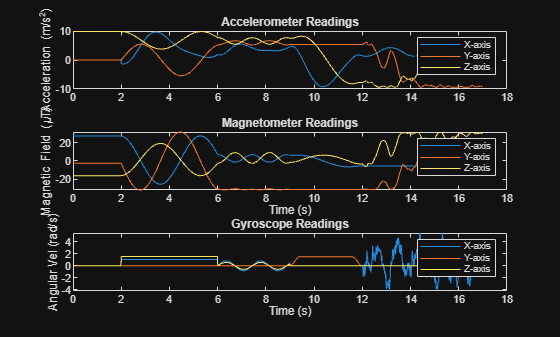

fs = imu.SampleRate;

segmentsAngVel = [
  struct("type","static","duration",2.0,"params",struct())
  struct("type","const_rot","duration",4.0,"params",struct("omega",[2*pi/6 0 2*pi/4]))
  struct("type","sin_rot","duration",3.0,"params",struct("axisUnit",[sqrt(2) 0 1],"amp",1.0,"freq",0.7,"phase",0))
  struct("type","stop_go","duration",3.0,"params",struct("axis",2,"omega",1.5,"rampTime",0.4))
  struct("type","bandlimited_random_rot","duration",5.0,"params",struct("axis",1,"amp",2.0,"cutoff",1.0))
];

segmentsAcc = [
    struct("type","static","duration",2.0,"params",struct())
    struct("type","sin_accel","duration",13.0,"params",struct("axis",1,"amp",1.5,"freq",0.5,"phase",pi/3))
    struct("type","static","duration",2.0,"params",struct())
];


[angVelBody] = buildAngVelDataset(fs, segmentsAngVel);
[accBody] = buildAccDataset(fs, segmentsAcc);

size(angVelBody);
size(accBody);


traj = kinematicTrajectory('SampleRate', fs);
[~, orientationNED, ~, accNED, angVelNED] = traj(accBody, angVelBody);

[accelReadings, gyroReadings, magReadings] = imu(accNED, angVelNED, orientationNED);



    

figure(1)
t = (0:(1700-1))/imu.SampleRate;
subplot(3,1,1)
plot(t,accelReadings)
legend('X-axis','Y-axis','Z-axis')
ylabel('Acceleration (m/s^2)')
title('Accelerometer Readings')

subplot(3,1,2)
plot(t,magReadings)
legend('X-axis','Y-axis','Z-axis')
ylabel('Magnetic Field (\muT)')
xlabel('Time (s)')
title('Magnetometer Readings')

subplot(3,1,3)
plot(t,gyroReadings)
legend('X-axis','Y-axis','Z-axis')
ylabel('Angular Vel (rad/s)')
xlabel('Time (s)')
title('Gyroscope Readings')

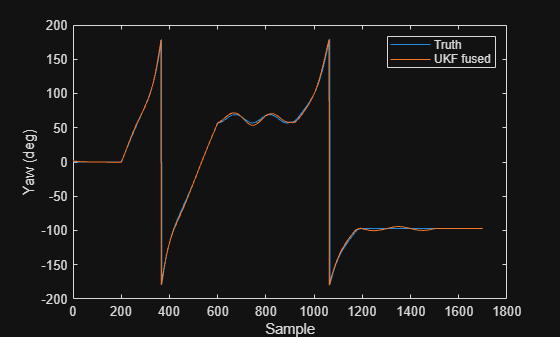




function xNext = ukfStateFcn(x,u,dt)
    % x = [qw qx qy qz bgx bgy bgz]'
    % u = [wx wy wz]' gyro measurement (rad/s)
    
    q  = x(1:4).';     % row vector for quatmultiply
    bg = x(5:7).';     % 1x3

    % Bias-corrected gyro
    omega = u.' - bg;  % 1x3

    dq = deltaQuatFromGyro(omega, dt);   % 1x4 [w x y z]

    % Propagate quaternion
    qNext = quatmultiply(q, dq);         % 1x4
    qNext = qNext / norm(qNext);

    % Simple model: gyro bias is constant (random walk handled by Q)
    bgNext = bg;

    xNext = [qNext.'; bgNext.'];         % 7x1 column
end



function z = ukfMeasFcn(x, g_n, m_n)
    q = x(1:4).';              % [w x y z]

    qObj = quaternion(q);
    % Use rotateframe to go from nav -> body
    a_pred = rotateframe(qObj, g_n.');   % 1x3
    m_pred = rotateframe(qObj, m_n.');   % 1x3

    z = [a_pred.'; m_pred.'];           % 6x1
end

dt = 1/imu.SampleRate;

orientation0 = ecompass(accelReadings(1,:), magReadings(1,:));
q0 = compact(orientation0);

m_n = imu.MagneticField.';
g_n = [0; 0; 9.81];  

stateTransitionFcn = @(x,u) ukfStateFcn(x,u,dt);
measurementFcn     = @(x) ukfMeasFcn(x, g_n, m_n);

% Initial state: identity quaternion, zero bias
x0 = [q0(:);   0;0;0];

ukf = unscentedKalmanFilter( ...
    stateTransitionFcn, ...
    measurementFcn, ...
    x0, ...
    'HasAdditiveMeasurementNoise', true);

% Rough initial covariance (ask about tuning)
ukf.StateCovariance = diag([1e-4*ones(1,4), 1e-3*ones(1,3)]);

% Process and measurement noise (ask about tuning)
ukf.ProcessNoise     = diag([1e-6*ones(1,4), 1e-6*ones(1,3)]);
ukf.MeasurementNoise = diag([ (0.1*9.81)^2*ones(1,3),  (0.5)^2*ones(1,3) ]);

numSamples = size(accelReadings,1);
xHat = zeros(7,numSamples);

for k = 1:numSamples
    u_k = gyroReadings(k,:).';                       
    z_k = [accelReadings(k,:).'; magReadings(k,:).']; 

    predict(ukf, u_k);     

    correct(ukf, z_k);     

    xHat(:,k) = ukf.State;
end

q_hat = xHat(1:4,:).';  

q_rel = quatmultiply(quaternion(q_hat), conj(orientationNED));


yawPitchRoll_truth = eulerd(quaternion(orientationNED),'ZYX', 'frame');
yawPitchRoll_ukf  = eulerd(quaternion(q_hat), 'ZYX', 'frame');


yawPitchRoll_compare = eulerd(quaternion(q_rel), 'ZYX', 'frame');

figure;
plot(yawPitchRoll_truth(:,1), 'DisplayName','Truth'); hold on;
plot(yawPitchRoll_ukf(:,1),  'DisplayName','UKF fused');
xlabel('Sample'); ylabel('Yaw (deg)');
legend;

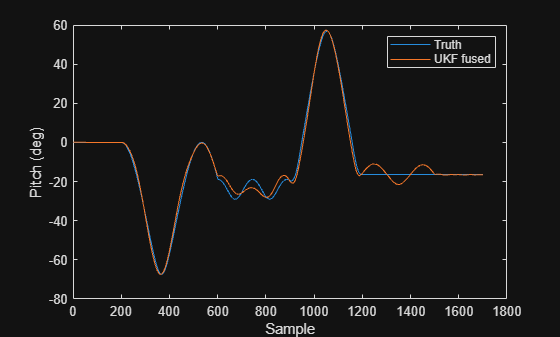


figure;
plot(yawPitchRoll_truth(:,2), 'DisplayName','Truth'); hold on;
plot(yawPitchRoll_ukf(:,2),  'DisplayName','UKF fused');
xlabel('Sample'); ylabel('Pitch (deg)');
legend;

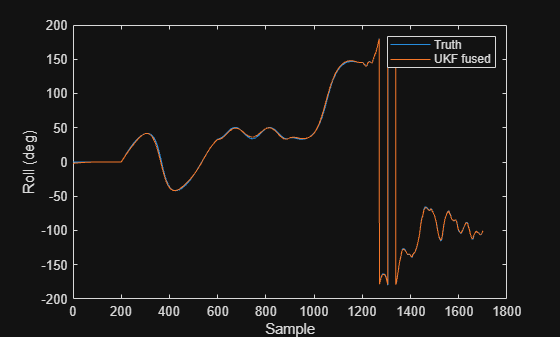


figure;
plot(yawPitchRoll_truth(:,3), 'DisplayName','Truth'); hold on;
plot(yawPitchRoll_ukf(:,3),  'DisplayName','UKF fused');
xlabel('Sample'); ylabel('Roll (deg)');
legend;

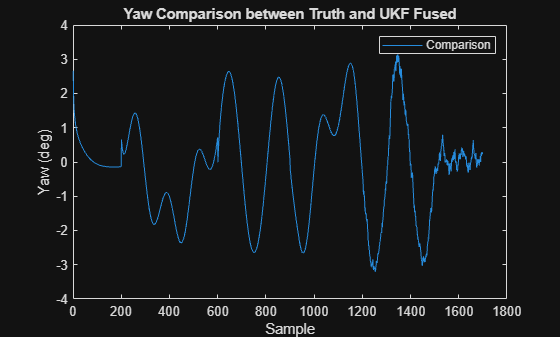


figure;
plot(yawPitchRoll_compare(:,1), 'DisplayName','Comparison');
xlabel('Sample'); ylabel('Yaw (deg)');
legend;
title('Yaw Comparison between Truth and UKF Fused');

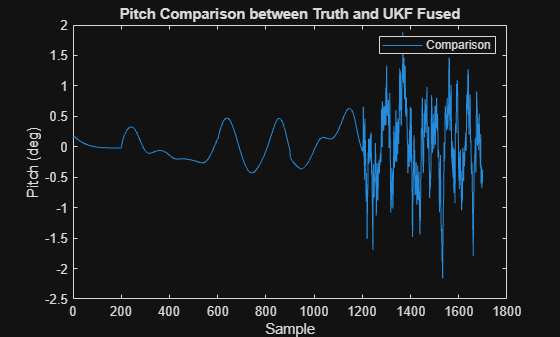


figure;
plot(yawPitchRoll_compare(:,2), 'DisplayName','Comparison');
xlabel('Sample'); ylabel('Pitch (deg)');
legend;
title('Pitch Comparison between Truth and UKF Fused');

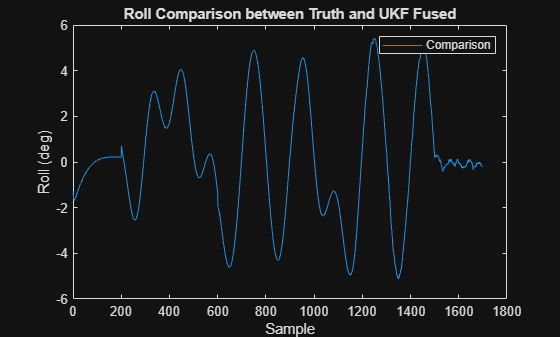


figure;
plot(yawPitchRoll_compare(:,3), 'DisplayName','Comparison');
xlabel('Sample'); ylabel('Roll (deg)');
legend;
title('Roll Comparison between Truth and UKF Fused');